clear all; clc
Ea = 13.4E10; %elastic modulus ceramic
Em = 200E9; %[MPa]; %elastic modulus steel

rho_s = 7.8E3; %kg/m^3
rho_a = 7.7E3; %kg/m^3
U0 = 3.3; %micrometers
ha0 = 2E-3; %m

Fout = 1100; %Newton

a_a0 = 1;
a_astep = 1;
a_a1 = 200;
A_T = [a_a0:a_astep:a_a1]*1E-6;
A_c = [a_a0+1:a_astep:a_a1]*1E-6;

K1 = length(A_T);
K2 = length(A_c);
A_a = (5E-3)^2;


h0 = 30; 
h1 = 80;
h_step = 0.1;
h = (h0:h_step:h1)*1E-3;
L1 = length(h);

La0 = 2;
La1 = 50;
La_step = 2; %each plate is 2mm
La = [La0:La_step:La1]*1E-3;
L2 = length(La);

alpha = zeros(L1,L2);
L_T = zeros(L1,L2);
ia = zeros(L1,L2);
iT = zeros(L1,L2);

CT = zeros(L1,L2);
Cc = zeros(L1,L2);
Ca = zeros(L1,L2);
Ctot = zeros(L1,L2);
Csys = zeros(L1,L2);
        
massa = zeros(L1,L2);
massc = zeros(L1,L2);
masst = zeros(L1,L2);
masstotal = zeros(L1,L2);
specc = zeros(L1,L2);
sc = zeros(K1,K2);
for k = 1:K1
    for l = 1:K2
for i=1:L1
    for j=1:L2
        %dimensions 
        alpha(i,j) = atan(h(i)/La(j));
        L_T(i,j) = La(j)/(2*cos( alpha(i,j) ) );
        
        %transmission ratio's
        ia(i,j) = La(j)/h(i);
        iT(i,j) = sin(alpha(i,j));
 
        
        %stiffnesses
        CT(i,j) = Em * A_T(k) / L_T(i,j);
        Cc(i,j) = Em * A_c(l) / h(i);
        Ca(i,j) = Ea * A_a / La(j);
        Ctot(i,j) = Cc(i,j) + 0.5*CT(i,j)*iT(i,j) + Ca(i,j)*ia(i,j);
        Csys(i,j) = ((Cc(i,j))^-1 + (2*CT(i,j)/iT(i,j))^-1)^-1;
        
        %output stroke
        Fpreload = 1.1 * ia(i,j);
        umax(i,j) = ((La(j)-La0*1E-3)/(La0*1E-3))*U0;
        xp(i,j) = (umax(i,j)+Fpreload/Ca(i,j))/(1+(Csys(i,j)/Ca(i,j)));
        S_out(i,j) = umax(i,j)*ia(i,j);
        Isgood(i,j) = (S_out(i,j) >= 6) && (S_out(i,j) <= 6.5);
        Isgoodsurf(i,j) = (S_out(i,j) >= 6);
        S_outgoodsurf(i,j) = Isgoodsurf(i,j)*S_out(i,j);
  
        iagood(i,j) =  ia(i,j)*Isgood(i,j);

        
        massa(i,j) = rho_a*A_a*La(j);
        massc(i,j) = rho_s*A_c(l)*h(i);
        masst(i,j) = 4*rho_s*A_T(k)*(L_T(i,j));
        masstotal(i,j) = massa(i,j)+massc(i,j)+masst(i,j);
        specc(i,j) = (Ctot(i,j)/masstotal(i,j))*Isgood(i,j);
   

    end
end
   maxstiff(k,l) = max(max(Ctot));
   meanstiff(k,l) = mean(nonzeros(Ctot));
 maxsc(k,l) = max(max(specc));
meansc(k,l) = mean(nonzeros(specc));

    end
end




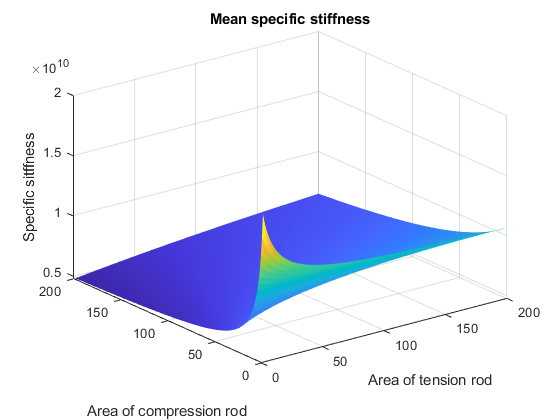

[X,Y] = meshgrid([a_a0+1:a_astep:a_a1],[a_a0:a_astep:a_a1]);

figure 
clf
s1 = surf(X,Y,meansc);
s1.EdgeColor = 'none';

title('Mean specific stiffness')
xlabel('Area of tension rod')
ylabel('Area of compression rod')
zlabel('Specific sitffness')
saveas(gcf,'ssa11/meanspecificstiff.png')

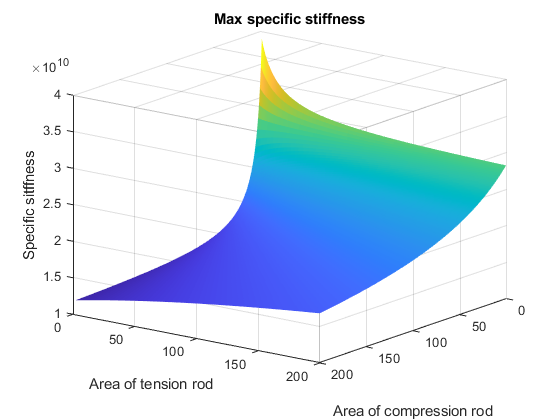




figure 
clf
s1 = surf(X,Y,maxsc);
s1.EdgeColor = 'none';

title('Max specific stiffness')
xlabel('Area of tension rod')
ylabel('Area of compression rod')
zlabel('Specific sitffness')
saveas(gcf,'ssa11/maxspecificstiff.png')

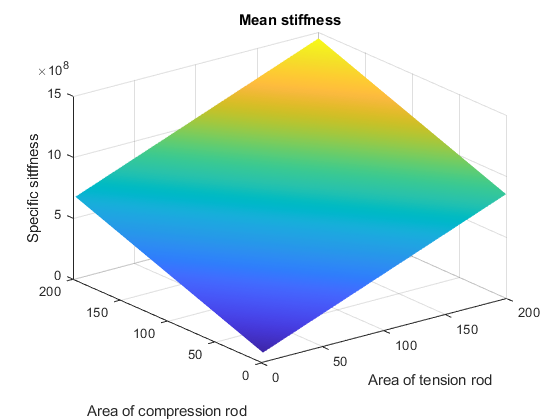



figure 
clf
s1 = surf(X,Y,meanstiff);
s1.EdgeColor = 'none';

title('Mean stiffness')
xlabel('Area of tension rod')
ylabel('Area of compression rod')
zlabel('Specific sitffness')
saveas(gcf,'ssa11/meanstiff.png')

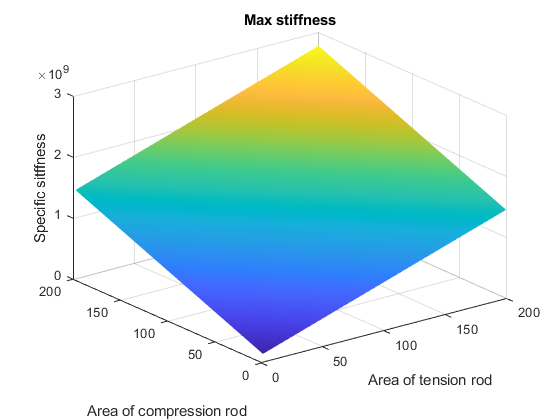




figure 
clf
s1 = surf(X,Y,maxstiff);
s1.EdgeColor = 'none';

title('Max stiffness')
xlabel('Area of tension rod')
ylabel('Area of compression rod')
zlabel('Specific sitffness')
saveas(gcf,'ssa11/maxstiff.png')